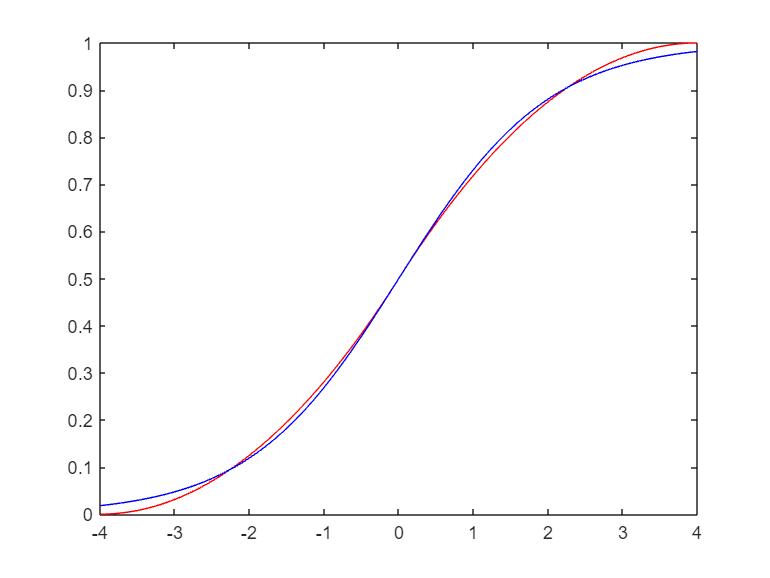

clear
close all;
clc

data=load('D:\PDS\AI\sigmoid\data\data_xy.txt');
x=data(:,1);
y1=data(:,2);

x11 = x/(2^14);
y22=1./(1.0+exp(-1.0*x11)); %sigmoid

y11=(y1/(2^28));
eer=y22-y11;

plot(x11,y11,'r',x11,y22,'b')

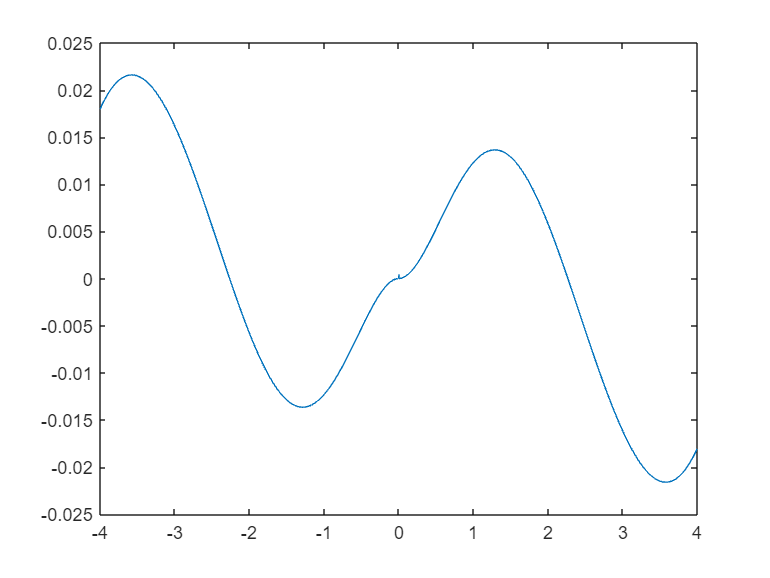

plot(x11,eer)


%[a1,b1] = findpeaks(eer);  % 极大值
%[a2,b2] = findpeaks(-eer); % 极小值